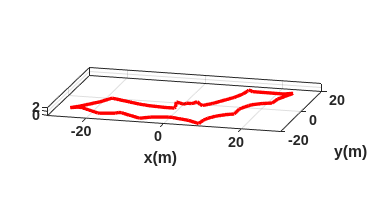

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 14;             % Tiempo de simulacion en segundos (s)
ts = 0.1;            % Tiempo de muestreo en segundos (s)
t = 0: ts: tf;       % Vector de tiempo
N = length(t);       % Muestras

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posicion en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posicion en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = 0;    % Posicion inicial eje x
y1(1) = -1;   % Posicion inicial eje y
phi(1) =0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

% Parámetros de los giros y movimientos
angles = [pi/3, -pi/3, pi/3, pi/10, -pi/1.3, pi/8, pi/2, pi/18,0, pi/18,...
          pi/18, pi/18, -pi/1.3, pi/4, 0, 0, pi/6, -pi/1.3, 0, pi/12, ...
          -pi/3, pi/12, pi/12, pi/12, pi/9,-pi/3,pi/12, pi/12,pi/12, pi/18, ...
          -pi/1.5, pi/12, pi/12, pi/9, pi/9, -pi/2.6, 0, -pi/18, pi/3, -pi/18,...
          pi/4, -pi/5, -pi/6, -pi/8, 0, pi/6, pi/5, -pi/1.1, pi/18, 0, ...
          pi/18, -pi/2, 0, pi/21, pi/21, pi/21, 0, pi/2, pi/15, -pi/1.3]; % Ángulos de giro (puedes modificarlos)
distances = [1.2, 1.2, 1.2, 1.2, 3, 1, 3, 4, 4, 4,...
             3, 1.3, 2, 3, 2, 3, 2.5, 3.8, 3, 4, ...
             2.5, 2.5, 1.5, 4, 5, 2, 3, 3, 2, 3.5, ...
             4, 5, 0.8, 4.5, 3, 3, 3, 1, 0.4, 0.4,...
             1, 4, 0.5, 4.5, 2, 1, 2, 2.5, 3.5, 3.5,...
             4.5, 4.5, 4.5, 3 , 4, 2.5, 3, 1, 5, 3]; % Distancias de los movimientos lineales en metros (puedes modificarlas)
duration_turn = [1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts,1/0.1*ts, 1/0.1*ts,...
                 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts,...
                 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts,...
                 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts,...
                 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, ...
                 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts, 1/0.1*ts];     % Duración de cada giro (puedes ajustarlo)
duration_lineal = [0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1,0.1, 0.1,...
                   0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1,...
                   0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1,...
                   0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1, ...
                   0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1, ...
                   0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0,1, 0.1, 0.1, 0.1]; % Duración de cada movimiento lineal en segundos (puedes ajustarlo)

u = zeros(1,N); % Velocidad lineal (m/s)
w = zeros(1,N); % Velocidad angular (rad/s)

% Generación de las velocidades de referencia
idx_start = 1;
for i = 1:length(angles)
    % Duración del giro
    idx_end_turn = idx_start + duration_turn(i) - 1; % Índice final para el giro, ajustado por duration_turn(i)
    if idx_end_turn <= N
        w(idx_start:idx_end_turn) = angles(i) / (duration_turn(i) * ts); % Giro con el ángulo correspondiente
    end
    % Calcular la velocidad lineal basada en la distancia y la duración
    velocity_linear = distances(i) / duration_lineal(i); % Velocidad lineal calculada
    % Duración variable basada en la distancia y la velocidad lineal
    duration_segment = duration_lineal(i) / ts; % Duración en términos de muestras
    idx_start_move = idx_end_turn + 1;
    idx_end_move = idx_start_move + duration_segment - 1; % Duración del movimiento rectilíneo

    if idx_end_move <= N
        u(idx_start_move:idx_end_move) = velocity_linear; % Movimiento rectilíneo con velocidad calculada
    end

    % Actualización de índice para el sipi/3, -pi/3, pi/3, pi/10, -pi/1.3, pi/8, pi/2, pi/18guiente giro
    idx_start = idx_end_move + 1;
end


%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N
    phi(k+1)=phi(k)+w(k)*ts;
    xp1=u(k)*cos(phi(k+1));
    yp1=u(k)*sin(phi(k+1));
    x1(k+1)=x1(k) + xp1*ts;
    y1(k+1)=y1(k) + yp1*ts;
    hx(k+1)=x1(k+1);
    hy(k+1)=y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

scene=figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen=get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
view([15 15]);
axis([-30 30 -20 20 0 2]);

scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

step=1;
for k=1:step:N
    delete(H1);
    delete(H2);
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    pause(ts);
end